fname = '20170423wjz_L_rest_shp1_500hza12.txt'

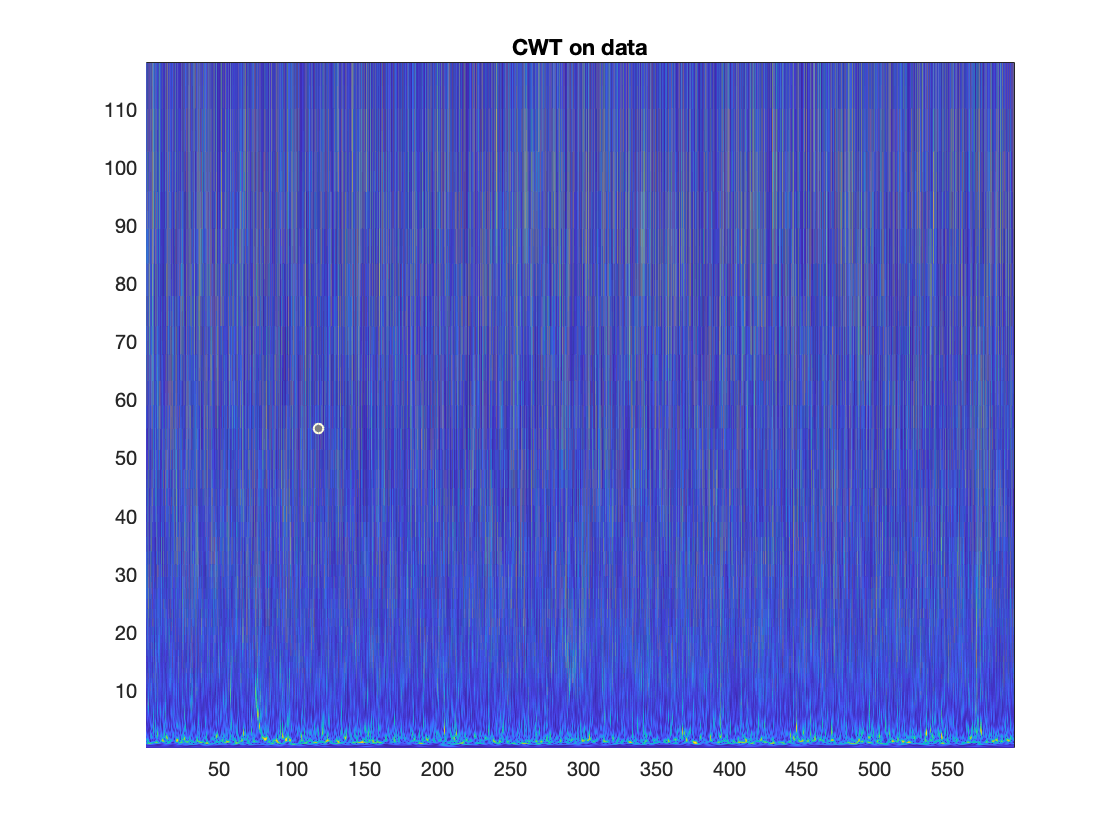

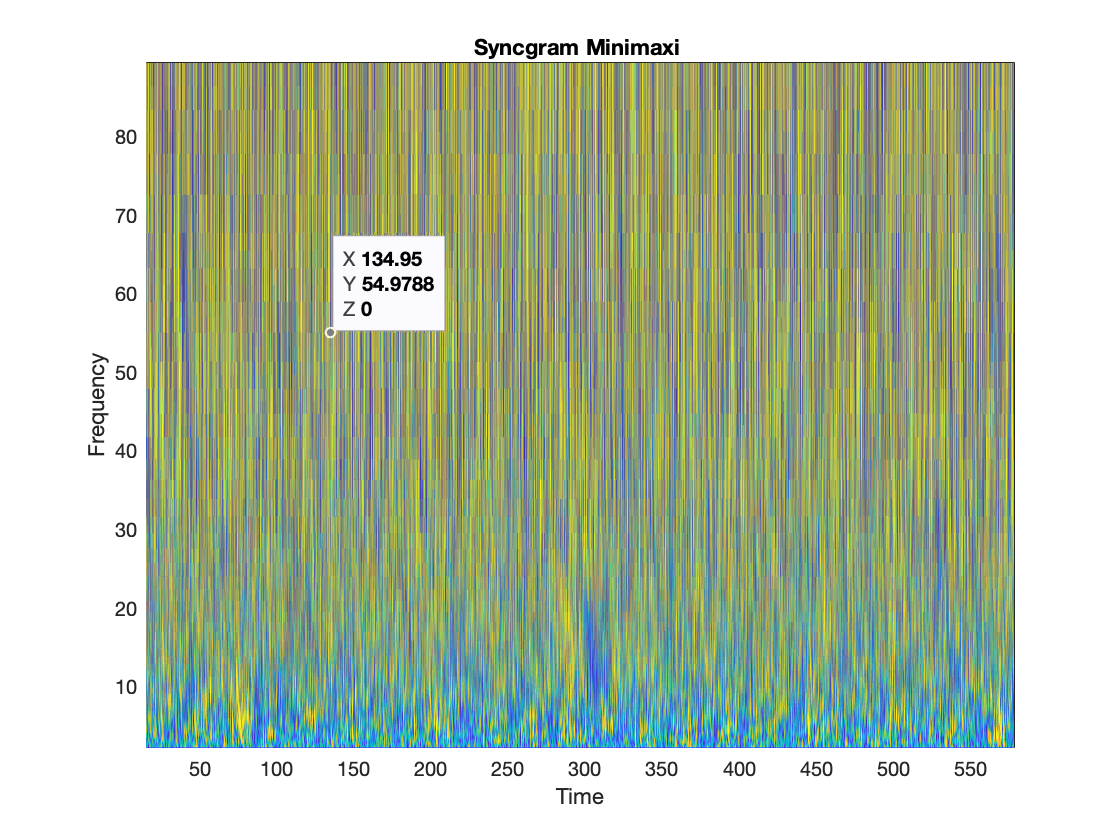

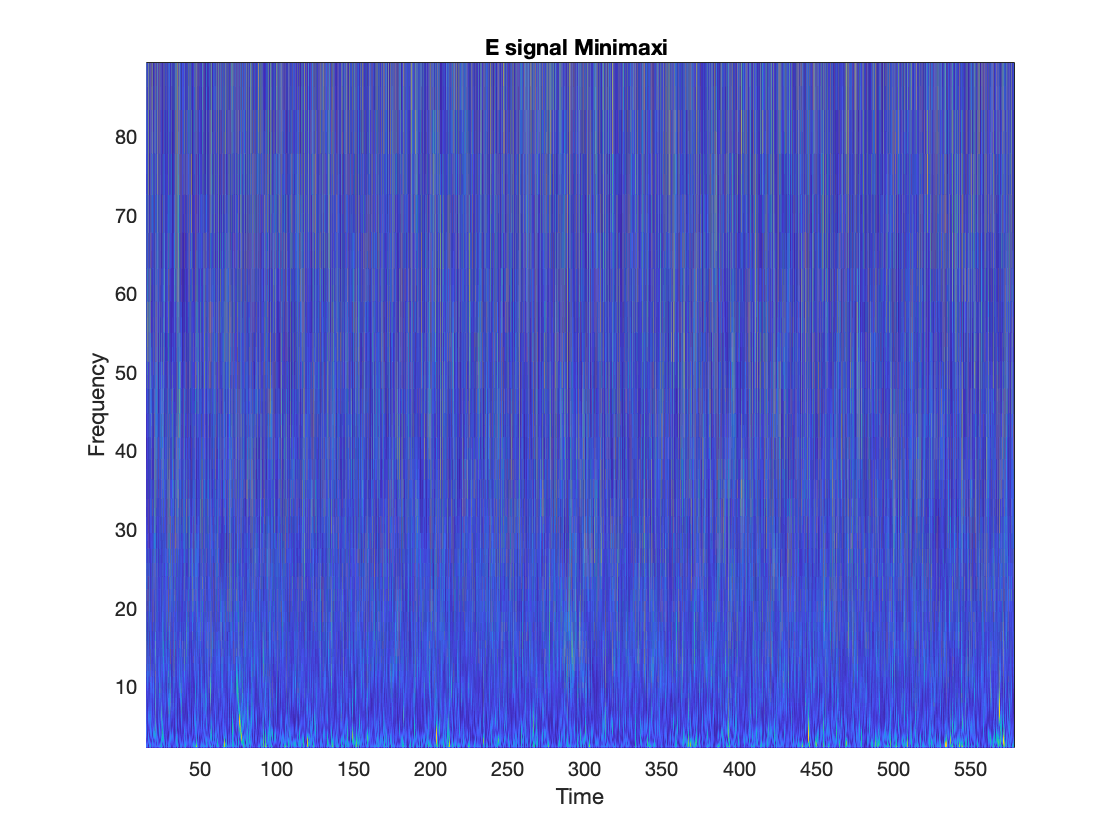

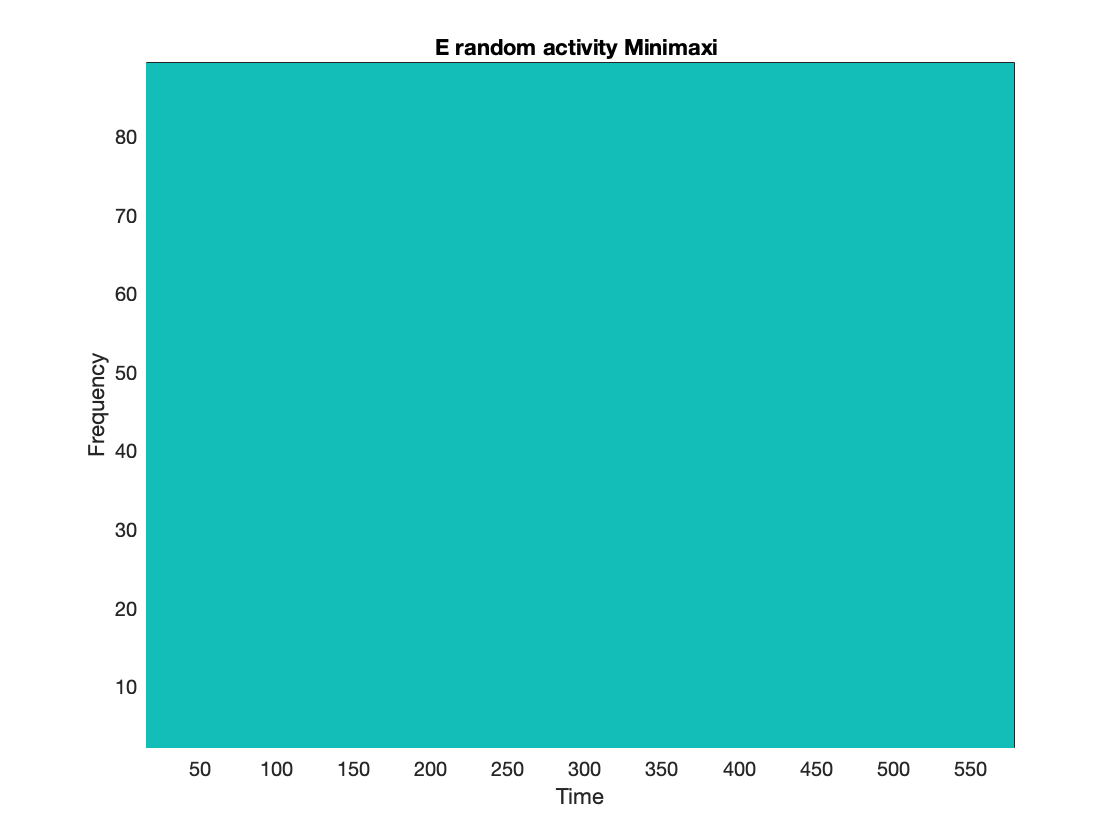

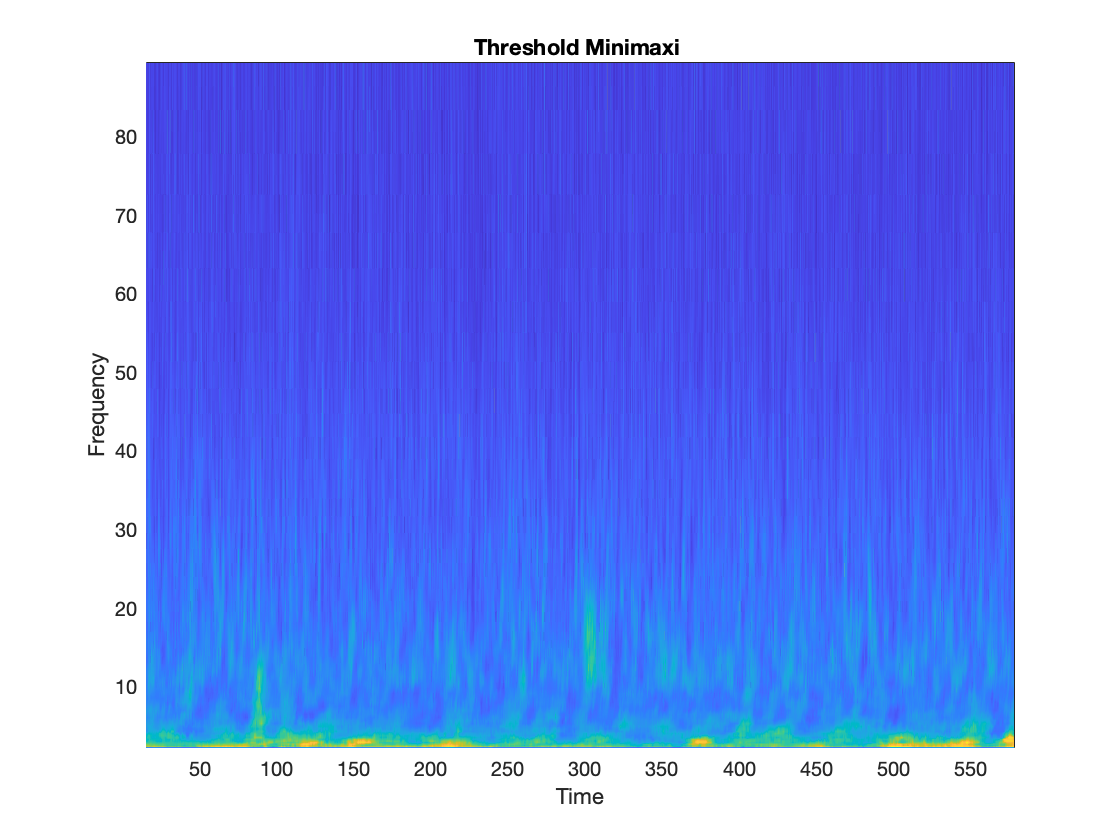

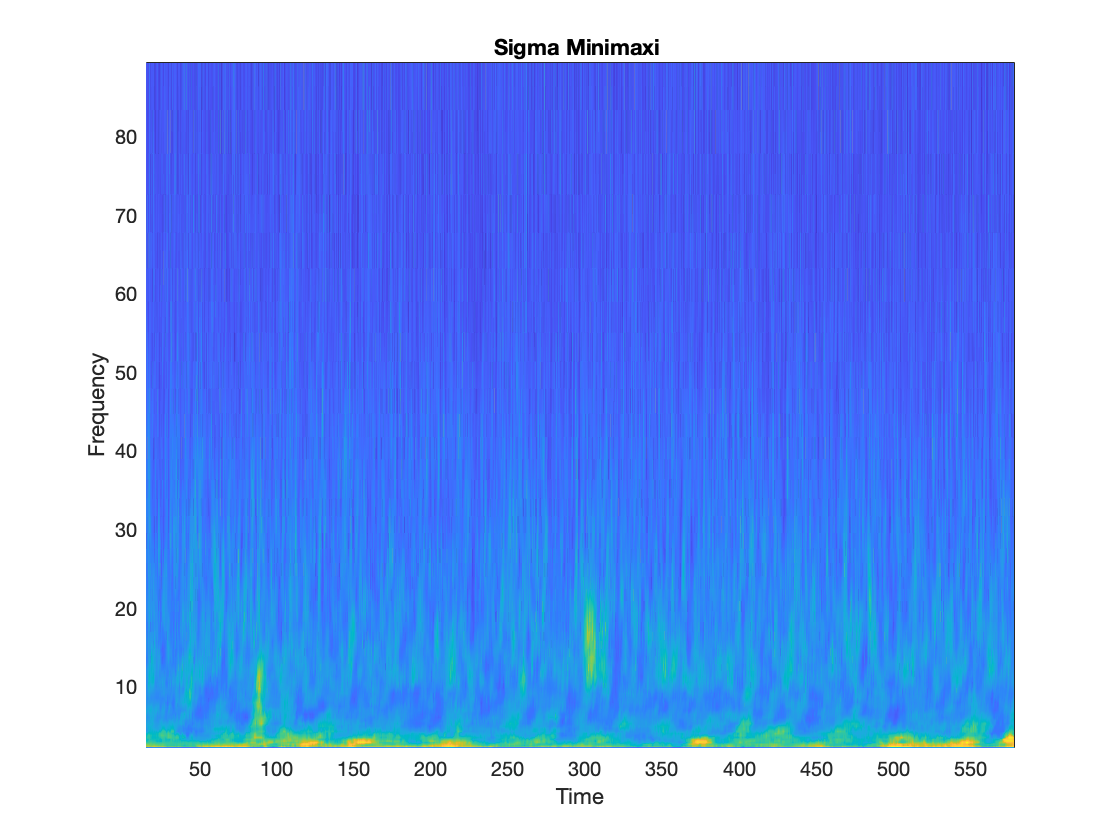

Unrecognized function or variable 'stateScaled'.

Error in NeuralSynCWT (line 267)
        varargout{1} = stateScaled;

%写一个具体的流程图给老师

% 窗长和频率相关
% rigsure加平滑
% 2% control chart
% bayes threshold

clc; clear;
warning off;

fs=500;%采样频率


% % load all files in selected folder
ftype='.txt';
pname='/Users/yskj/Desktop/项目/LFPDecoding/fixed_data/';

txtfile = [pname,'*',ftype];
file  = dir(txtfile);
nside = size(file,1);
Mean  = zeros(1, nside);
Var   = zeros(1, nside);
ERROR = zeros(1, nside);
 
for iside=1:nside%21
%iside = 1;

fname=file(iside).name
impfilename=[pname,fname];
sori=importdata(impfilename,'\t',1);

%{
load("LFP_delete15.mat");
sPAG=LFP_delete15(:,1);
fsResample = 256;
sPAGResample=resample(sPAG,fsResample,fs);

signal = sPAGResample;

%}

%2.5-5:  fsResample = 320;node=[6 6];centralFreq = 4;
%5-10:   fsResample = 320;node=[6 5];centralFreq = 7;
%10-20:  fsResample = 320;node=[6 4];centralFreq = 15;
%20-40:  
fsResample = 320;node=[6 3];%centralFreq = 30;


%6-12 :fsresample = 384;node=[5 5];
%12-24:fsresample = 384;node=[5 4];

%layerNum = node(1);
%FrequencyBand = node(1);
sgpi=sori.data(:,2);
sgpiResample=resample(sgpi,fsResample,fs);
signal = sgpiResample(fsResample*5:fsResample*10*60);

[states, tVector] = NeuralSynCWT(signal, fsResample);

%{
figure;
h1 = histogram(states);
title(['Syncronization Metric Histogram window = ',num2str(1/centerFreq * 60),'s']);
%}
end